dirs = dir("Simulations/2023_2T_yaw_steering_Demo/Results/yawBruteForce/");
M = readtable([dirs(3).folder filesep dirs(3).name]);

## Allocate stored signals

P       = zeros(height(M),length(dirs)-2);
Ueff    = zeros(height(M),length(dirs)-2);
FRed    = zeros(height(M),length(dirs)-2);
t       = unique(M.Time_s_);
gamma   = zeros(length(dirs)-2,2);

Go through all files and extract the needed data

for iD = 3:length(dirs)
    M = readtable([dirs(iD).folder filesep dirs(iD).name]);
    
    P(:,iD-2)     = M.PowerGenerated_MW_;
    Ueff(:,iD-2)  = M.EffectiveWindSpeed_ms__1_;
    FRed(:,iD-2)  = M.ForeignReduction___;
    gamma(iD-2,:) = [str2double(dirs(iD).name(1:3)), str2double(dirs(iD).name(5:7))];
end

# Plot

## Power Generated normalized

idx = find(ismember(gamma,[.5,.5],'rows'));
if isempty(idx); error('No norm case.'); end

P_norm_T1 = P(1:2:end,:)./P(1:2:end,idx);

P_norm =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1
     1     1     1     1     1     1     1     1     1     1     1     1     1     1    

P_norm_T2 = P(2:2:end,:)./P(2:2:end,idx);
P_norm = (P(1:2:end,:) + P(2:2:end,:))./(P(1:2:end,idx) + P(2:2:end,idx));

Special to this data set

X = reshape(gamma(3:end,1),11,[]);
Y = reshape(gamma(3:end,2),11,[]);

% Sort
Y([end-1,end],:) = Y([end,end-1],:);
Y = circshift(Y,1,1);

P_norm_plt = reshape(P_norm(241,3:end)',11,[]);
P_norm_plt([end-1,end],:) = P_norm_plt([end,end-1],:);
P_norm_plt = circshift(P_norm_plt,1,1);

[~,idx] = max(P_norm_plt,[],'all');


% Plot!
%surf(X,Y,P_norm_plt)
figure
contourf(X,Y,P_norm_plt,29,'EdgeColor','none')
hold on
scatter3(X(idx),Y(idx),P_norm_plt(idx),20,'k','filled')
hold off
axis equal
colormap(flipud(RdBu(29)))
caxis([min(P_norm_plt,[],'all'),2-min(P_norm_plt,[],'all')])
c = colorbar;
c.Label.String = 'P_{norm.}';
xlabel('\gamma_{1,n}')
ylabel('\gamma_{2,n}')
title(['k=' num2str(221)])

Stacked 

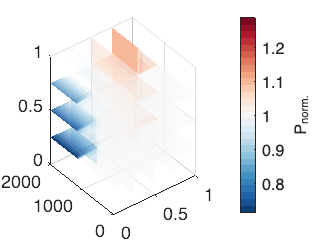


%[X,Y,Z] = ndgrid(t,unique(gamma(3:end,2)),unique(gamma(3:end,2)));
[X,Y,Z] = meshgrid(unique(gamma(3:end,2)),t,unique(gamma(3:end,1)));
figure
P_norm_plt = reshape(P_norm(:,3:end),[],11,10);
P_norm_plt(:,[end-1,end],:) = P_norm_plt(:,[end,end-1],:);
P_norm_plt = circshift(P_norm_plt,1,2);

%h = slice(X,Y,Z,P_norm_plt,[0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9],[],[0.1,0.2,0.3,0.4,0.5,0.6,0.7,0.8,0.9]);
%h = slice(X,Y,Z,P_norm_plt,.1:.1:.9,1000:100:1300,.1:.1:.9);
h = slice(X,Y,Z,P_norm_plt,[.25 .5 .75],[],[.25 .5 .75]);
set(h,'EdgeColor','none',...
'FaceColor','interp')
alpha('color')
alphamap('vdown')
colormap(flipud(RdBu(29)))
caxis([min(P_norm,[],'all'),2-min(P_norm,[],'all')])
c = colorbar;
c.Label.String = 'P_{norm.}';